%% SCRIPT FOR TESTING LIGHT PROPAGATION THROUGH BRAGG WITH GLASS
% -------------------------------------------------------------------------
%% GENERAL INPUT DATA
% -------------------------------------------------------------------------
lam = linspace(380, 1080, 851);
%
Bragg = repmat(["SiO2", "TiO2","TiO2","SiO2","TiO2","SiO2","TiO2"],1,1);
Bragg2 = repmat(["SiO2","SiO2","TiO2","SiO2","TiO2","SiO2"],1,1);
matPSC = [Bragg,"gls",Bragg2];
%
dgls = 2e6; dEVA = 2e6; dAZO = 5; dARC = 61.8;
dBragg =  [123.43, 5, 13.07, 47.199, 22.33428, 52, 12];
dBragg2=[29.02865,9,1,2.25,1.456788,83.80529]

dBragg2 =    29.0286    9.0000    1.0000    2.2500    1.4568   83.8053


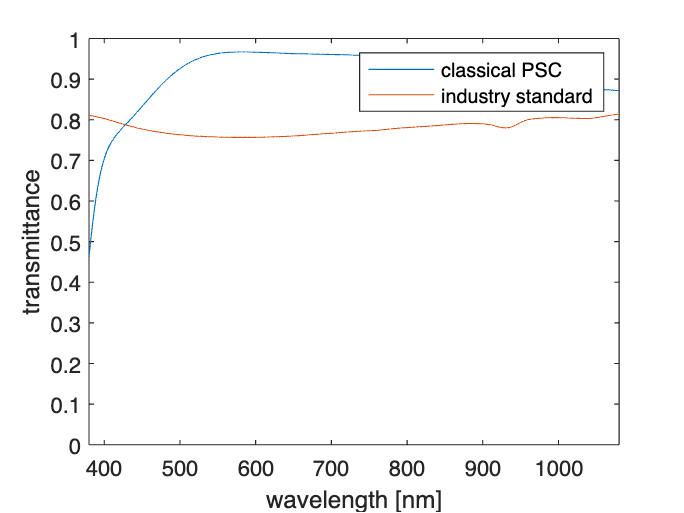

% SiO2/TiO2 x4
dPSC = [dBragg, dgls, dBragg2];
incoh = 1e3; % incoherent layer is 1000nm thickness
theta = 0;
% -------------------------------------------------------------------------
% DSM glass EVA PV
% -------------------------------------------------------------------------
materials = ["gls","EVA","const=2.4254","gls"];
d = [dEVA,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_DSM_EVA_PV, ~] = ATR1D( stack );
%
load("DSM.mat");
DSM_lam = interp1( DSM(:,1), DSM(:,2), lam, 'spline' )';
T_DSM_EVA_PV = T_DSM_EVA_PV.sp.*DSM_lam;                   
Jsc_DSM_EVA_PV = get_electric(lam, T_DSM_EVA_PV).jsc;
% -------------------------------------------------------------------------
% PSC with AZO and EVA on PV
% -------------------------------------------------------------------------
materials = ["air",matPSC,"AZO","EVA","const=2.4254","mSi"];
d = [dPSC,dAZO,dEVA,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, T_PSC_AZO_EVA_PV, ~] = ATR1D( stack );
Jsc_PSC_AZO_EVA_PV = get_electric(lam, T_PSC_AZO_EVA_PV.sp).jsc;
% -------------------------------------------------------------------------
% PLOTTING RESULTS
% -------------------------------------------------------------------------
figure();
plot(lam,T_PSC_AZO_EVA_PV.sp,lam,T_DSM_EVA_PV);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) lam(end)]); ylim([0 1]);
legend('classical PSC','industry standard')

%
disp(['Jsc for DSM standard: ' num2str(Jsc_DSM_EVA_PV)]);

Jsc for DSM standard: 28.3919


disp(['Jsc for classical PSC: ' num2str(Jsc_PSC_AZO_EVA_PV)]);

Jsc for classical PSC: 33.8765


disp(['Gain in Jsc: ' num2str((Jsc_PSC_AZO_EVA_PV/Jsc_DSM_EVA_PV-1)*100) '%']);

Gain in Jsc: 19.3175%
